# 案例：模拟退火求解旅行商问题

clear;clc;
ratio = 0.99;	    
t_start = 100; 
t_end = 1;        
Markov_length = 5000;	
coordinates = load('CityCoordinates.txt');
amount = size(coordinates, 1); 	% 城市的数目
% 通过向量化的方法计算距离矩阵
coor_x_tmp1 = coordinates(:,1) * ones(1, amount);
coor_x_tmp2 = coor_x_tmp1';
coor_y_tmp1 = coordinates(:, 2) * ones(1, amount);
coor_y_tmp2 = coor_y_tmp1';
dist_matrix = sqrt((coor_x_tmp1 - coor_x_tmp2).^2 + (coor_y_tmp1 - coor_y_tmp2).^2);
sol_new = 1 : amount;         % 产生初始解
% sol_new 是每次产生的新解；
% sol_current 是当前解；
% sol_best 是冷却中的最好解；
% E_current 是当前解对应的回路距离；
% E_new 是新解的回路距离；
% E_best 是最优解的
E_current = inf;        
E_best = inf; 		
sol_current = sol_new; 
sol_best = sol_new;
t = t_start;          
while t >= t_end
    % 当前温度下循环
    for r = 1 : Markov_length		
        % 产生随机扰动
        if (rand < 0.5)	% 随机决定是进行两交换还是三交换
            % 两交换
            ind = randperm(amount, 2);
            ind1 = ind(1);
            ind2 = ind(2);            
            tmp1 = sol_new(ind1);
            sol_new(ind1) = sol_new(ind2);
            sol_new(ind2) = tmp1;
        else
            % 三交换
            ind = randperm(amount, 3);
            % 确保ind1 < ind2 < ind3
            ind = sort(ind);
            ind1 = ind(1);
            ind2 = ind(2);
            ind3 = ind(3);
            tmplist1 = sol_new(ind1 + 1 : ind2 - 1);
            sol_new(ind1 + 1 : ind1 + ind3 - ind2 + 1) = sol_new(ind2 : ind3);
            sol_new(ind1 + ind3 - ind2 + 2 : ind3) = tmplist1;
        end       
        % 计算目标函数值
        E_new = 0;
        for i = 1 : amount - 1
            E_new = E_new + dist_matrix(sol_new(i), sol_new(i + 1));
        end
        % 再算上从最后一个城市到第一个城市的距离
        E_new = E_new + dist_matrix(sol_new(amount), sol_new(1));        
        if E_new < E_current
            E_current = E_new;
            sol_current = sol_new;
            if E_new < E_best
                % 把冷却过程中最好的解保存下来
                E_best = E_new;
                sol_best = sol_new;
            end
        else
            % 若新解的目标函数值大于当前解的，则仅以一定概率接受新解
            if rand < exp(-(E_new - E_current)/t)
                E_current = E_new;
                sol_current = sol_new;
            else
                sol_new = sol_current;
            end
        end
    end
    t = t * ratio;		% 降温
end
disp(['最优解为：', num2str(sol_best)]);

最优解为：45  32  49   1  22  31  18   3  17  21  42   7   2  30  23  20  50  29  16  46  44  34  35  36  39  40  37  38  48  24   5  15   6   4  25  12  28  27  26  47  13  14  52  11  51  33  43  10   9   8  41  19


disp(['最短距离：', num2str(E_best)]);

最短距离：7544.3659


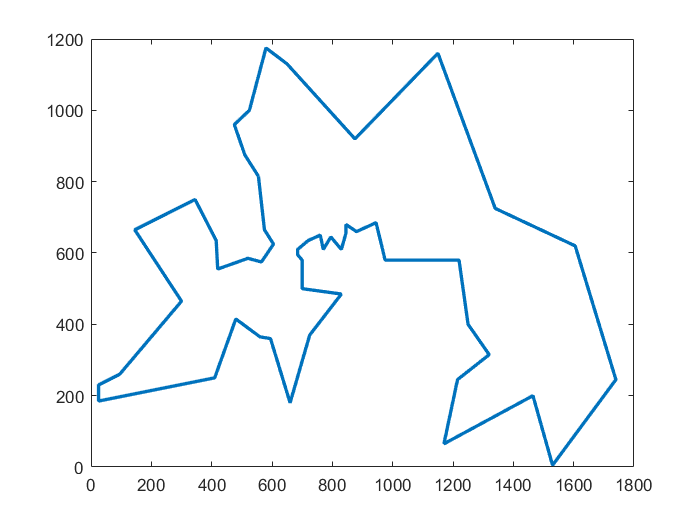

x_path = [coordinates(sol_best, 1); coordinates(sol_best(1), 1)];
y_path = [coordinates(sol_best, 2); coordinates(sol_best(1), 2)];
plot(x_path, y_path, 'LineWidth', 2)